% clc;
clear;

spotify = readtable('../datasets/spotify.csv');

## genre distribution

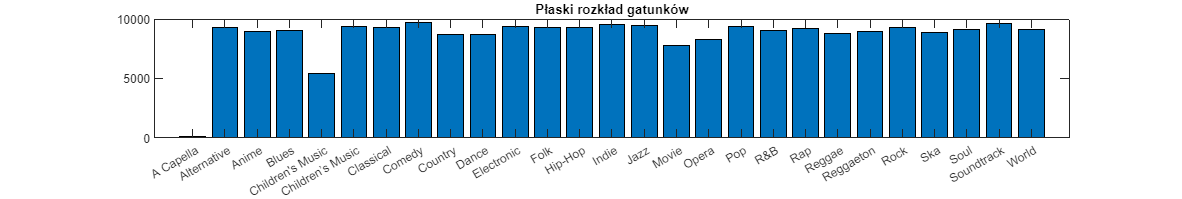

%flat histogram expected since thats how the dataset is defined
h1 = figure();
set(h1, 'Units', 'Normalized', 'Position', [0,0,1,.3]);

genresAggregated = groupcounts(spotify, "genre");
genres_barplot = bar(1:length(genresAggregated.genre), genresAggregated.GroupCount);
title('Płaski rozkład gatunków')
set(gca, 'xtick', 1:length(genresAggregated.genre));
set(gca,'xticklabel',genresAggregated.genre);

## mean genre popularity

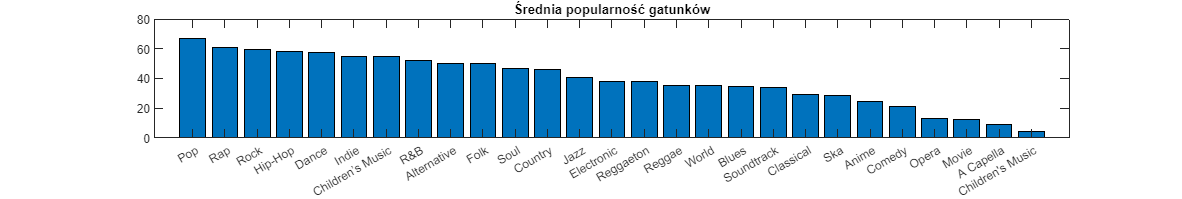

h2 = figure();
set(h2, 'Units', 'Normalized', 'Position', [0,0,1,.3]);

genre_and_popularity_cols = cell2table([spotify.genre, num2cell(spotify.popularity)], "VariableNames", ["genre", "popularity"]);
avgPopularity = groupsummary(genre_and_popularity_cols, "genre", "sum");
avgPopularity.mean_popularity = avgPopularity.sum_popularity ./ avgPopularity.GroupCount;
avgPopularity = sortrows(avgPopularity, 'mean_popularity', 'descend');

bar(1:length(avgPopularity.genre), avgPopularity.mean_popularity);
title('Średnia popularność gatunków')
set(gca, 'xtick', 1:length(avgPopularity.genre));
set(gca,'xticklabel',avgPopularity.genre);

## Brzmienie

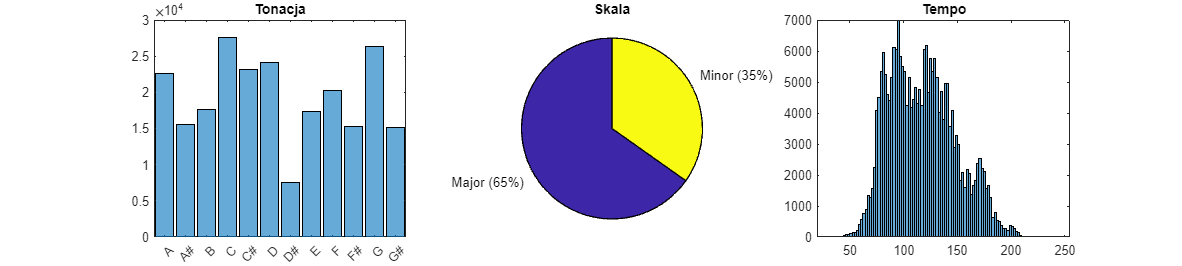

h3 = figure();
set(h3, 'Units', 'Normalized', 'Position', [0,0,1,.4]);

subplot(1,3,1);
spotify.key = categorical(spotify.key);
histogram(spotify.key)
title('Tonacja');

subplot(1,3,2);
spotify.mode = categorical(spotify.mode);
pie(spotify.mode);
title('Skala');

subplot(1,3,3);
histogram(spotify.tempo);
title('Tempo');

## Dance music's actual danceability

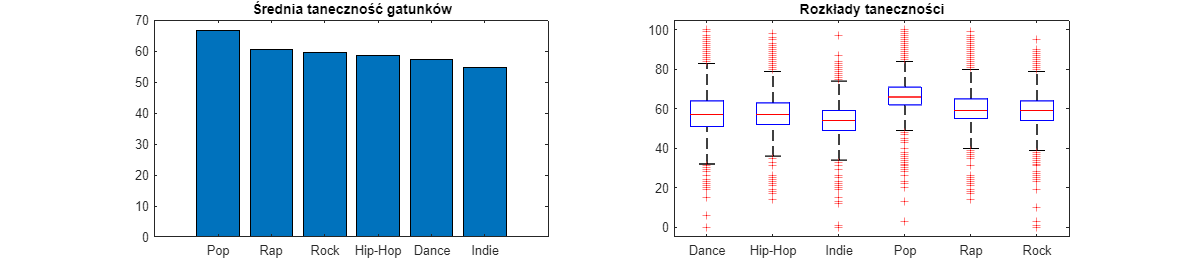

h4 = figure();
set(h4, 'Units', 'Normalized', 'Position', [0,0,1,.4]);

genre_and_danceability_cols = cell2table([spotify.genre, num2cell(spotify.popularity)], "VariableNames", ["genre", "danceability"]);
genre_and_danceability_cols.genre = categorical(genre_and_danceability_cols.genre);
avgDanceability = groupsummary(genre_and_danceability_cols, "genre", "sum");
avgDanceability.mean_danceability = avgDanceability.sum_danceability ./ avgDanceability.GroupCount;
avgDanceability = sortrows(avgDanceability, 'mean_danceability', 'descend');

subplot(1,2,1);
bar(1:length(avgDanceability.genre(1:6)), avgDanceability.mean_danceability(1:6));
title('Średnia taneczność gatunków')
set(gca, 'xtick', 1:length(avgDanceability.genre(1:6)));
set(gca,'xticklabel',avgDanceability.genre(1:6));

cond = logical( ...
    double((genre_and_danceability_cols.genre == 'Pop')) + ...
    double((genre_and_danceability_cols.genre == 'Rap')) + ...
    double((genre_and_danceability_cols.genre == 'Rock')) + ...
    double((genre_and_danceability_cols.genre == 'Hip-Hop')) + ...
    double((genre_and_danceability_cols.genre == 'Dance')) + ...
    double((genre_and_danceability_cols.genre == 'Indie')) ...
);
genre_and_danceability_cols_filtered = genre_and_danceability_cols(cond, :); 

subplot(1,2,2);
boxplot(genre_and_danceability_cols_filtered.danceability, genre_and_danceability_cols_filtered.genre);
title('Rozkłady taneczności')

## Electronic music's actual electronicness

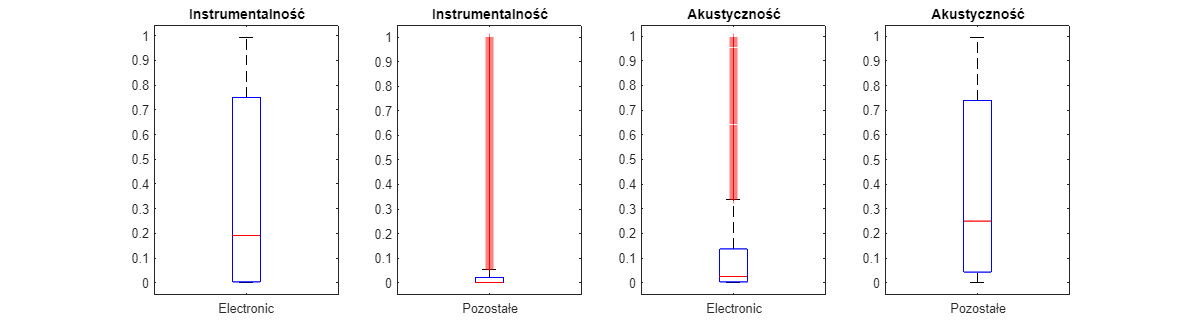

h4 = figure();
set(h4, 'Units', 'Normalized', 'Position', [0,0,1,.5]);

% TODO: jaka jest acousticness i instrumentalness dla Electronic na tle innych gatunkow
spotify.genre = categorical(spotify.genre);
electronic = spotify(spotify.genre == 'Electronic', :);
rest = spotify(spotify.genre ~= "Electronic", :);

subplot(1,4,1);
boxplot(electronic.instrumentalness, 'Labels', 'Electronic');
title('Instrumentalność');

subplot(1,4,2);
boxplot(rest.instrumentalness, 'Labels', 'Pozostałe');
title('Instrumentalność');

subplot(1,4,3);
boxplot(electronic.acousticness, 'Labels', 'Electronic');
title('Akustyczność');

subplot(1,4,4);
boxplot(rest.acousticness, 'Labels', 'Pozostałe');
title('Akustyczność');

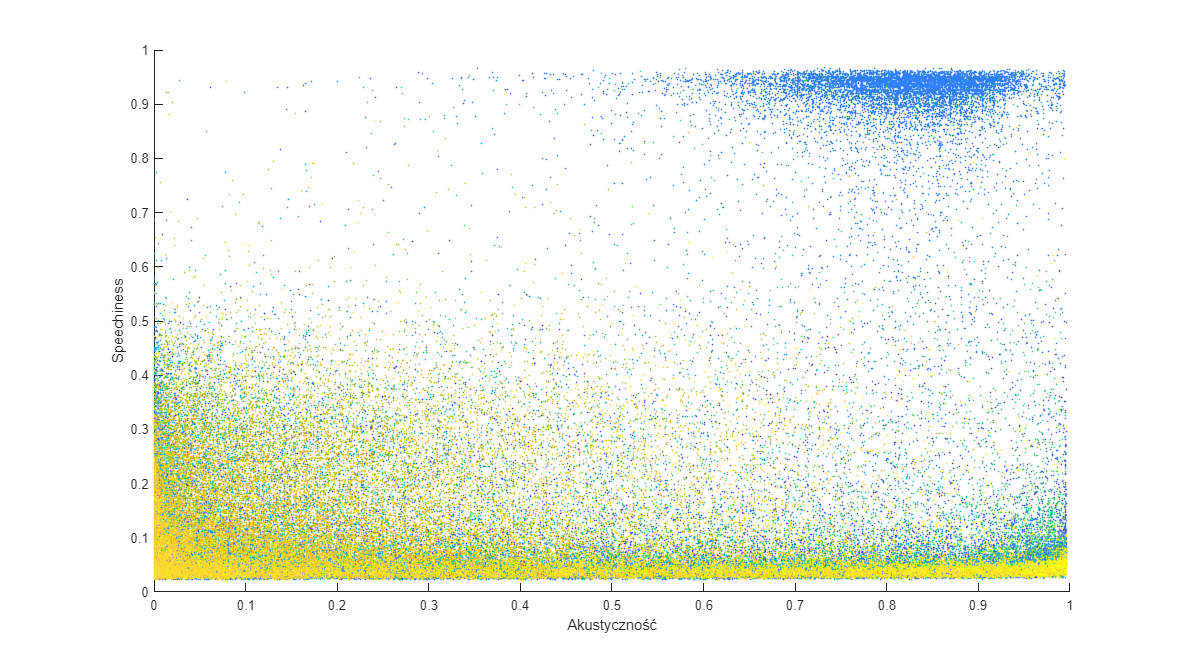

h6 = figure();
set(h6, 'Units', 'Normalized', 'Position', [0,0,1,1]);

% tu mozna by wybrac pare gatunkow tylko tak zeby sie roznily wyraznie w
% tych dwoch osiach (a nawet mozna je zmienic)

scatter(spotify.acousticness, spotify.speechiness, 1, spotify.genre, 'filled');
xlabel('Akustyczność');
ylabel('Speechiness');